clear all

home = true; %Set to true if working from home, false if working from school. 

%Set file paths for images to pixel label

if home
    addpath('F:\Research\Galapagos');
    filepath = ('F:\Research\Galapagos\Galapagos_imagery\Datastore');
else
    addpath('D:\Research\Galapagos');
    filepath = ('D:\Research\Galapagos\Galapagos_imagery\Datastore');
end

imds = imageDatastore(filepath,'FileExtensions','.jpg');

%Export ground truth from image labeler (gTruth.mat is output)

load gTruth.mat

% create pixel label datastore

pxds = pixelLabelDatastore(gTruth);

%create pixel label image datastore for training

pximds = pixelLabelImageDatastore(imds,pxds);  %%%needs to be same number of files

%set training options

options = trainingOptions('sgdm','InitialLearnRate',1e-3, ...
    'MaxEpochs',20,'VerboseFrequency',10);

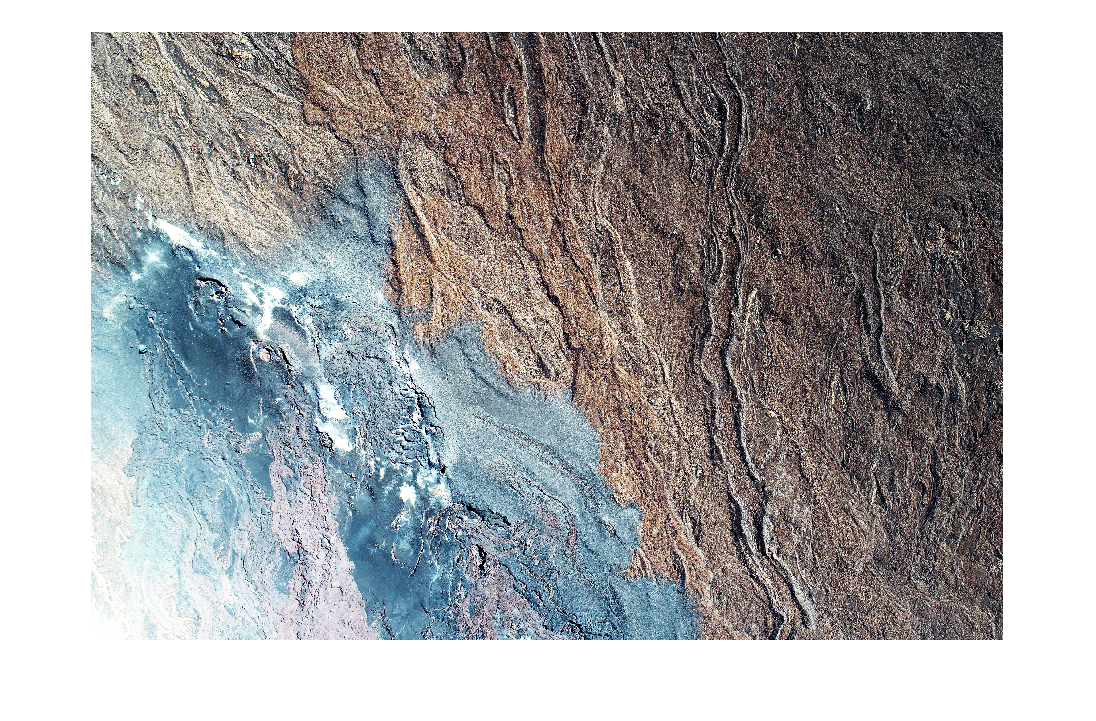

% Displaying a single raw image without overlay

I = readimage(imds,1);
I = histeq(I);
imshow(I)

% Set label classes

load galLabels.mat labelDefs; 
galLabels = labelDefs;
classes = galLabels{1:4,"Description"}; %Set classes as ROI descriptions

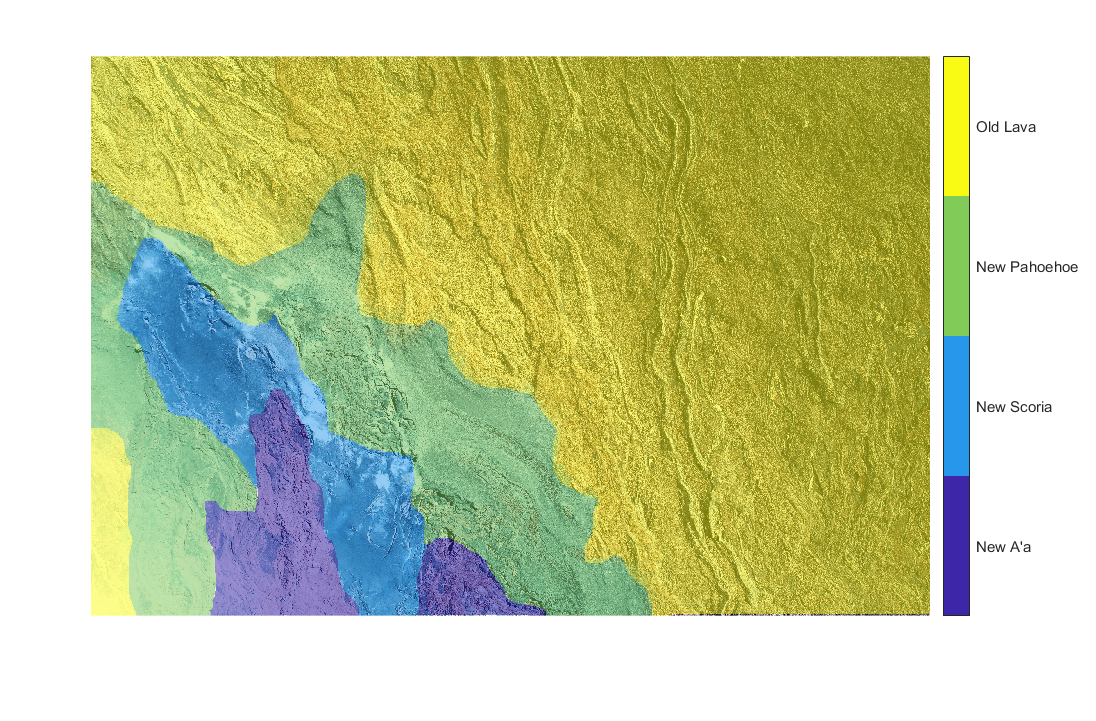

%Display training image with pixel label overlay

cmap = parula(numel(classes)); %set colormap

C = readimage(pxds,1);
B = labeloverlay(I,C,'ColorMap',cmap);
imshow(B)
pixelLabelColorbar(cmap,classes); %display color bar

%% Loop

% Set filepath to folder containing training images

% Set label classes from labelDefs

% Generate raw image(i) without overlay

% Generate image(i) with pixel label overlay and colorbar

% End?

% append_pdfs or print2array? 

%% WRite to file, don't display each one

% For testing

numfiles = numel(imds.Files);

outputFolder = 'F:\Research\Galapagos\Training Data\Raw';
if ~exist(outputFolder, 'dir')
  mkdir(outputFolder);
end

for i = 1:numfiles
    img = readimage(imds,i);
    img = histeq(img);
    
    baseFilename = sprintf('Training_raw%d.png', i);
    fullFilename = fullfile(outputFolder, baseFilename); 
    imwrite(img, fullFilename);
    
end


outputFolderLabels = 'F:\Research\Galapagos\Training Data\Labels';
if ~exist(outputFolder, 'dir')
  mkdir(outputFolder);
end

for i = 1:numfiles
    img = readimage(outputFolder,i);
    
    C = readimage(pxds,1);
    B = labeloverlay(img,C,'ColorMap',cmap);
    pixelLabelColorbar(cmap,classes); %display color bar

    % save this as a figure, then use saveas
    
    baseFilename = sprintf('Training_labels%d.png', i);
    fullFilename = fullfile(outputFolderLabels, baseFilename); 
   % saveas(__, fullFilename);
    
end